This live-script runs solvers for the 1D acoustics equations via staggered grid FD methods.

clear

% Computational and output grids
grid_cmp = GridSpace1D(Grid1DUnifPrimal([0,1],401));
grid_out = GridSpace1D(Grid1DUnifPrimal([0,1],101));

% Medium parameters
medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);

% Acoustic source
source = AcousticSource1D( ...
    @(x) exp(-((x-0.35)/0.04).^2), ...
    @(t) exp(-((t-0.12)/0.025).^2));

% Choose dt from the wave-speed CFL condition.
[~,~,~,cMax] = sampleMedium1D(grid_cmp,medium);
dt = 0.9*grid_cmp.h/cMax * 6/7;

% Time grids
times_cmp = 0:dt:1;
times_out = linspace(0,times_cmp(end),51);

% Initial data and a compact pressure source
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initializing solver
solver = AcousticSolver1DStaggered( ...
    grid_cmp,times_cmp, ...
    grid_out,times_out, ...
    medium, ...
    SpatialOrder=4);

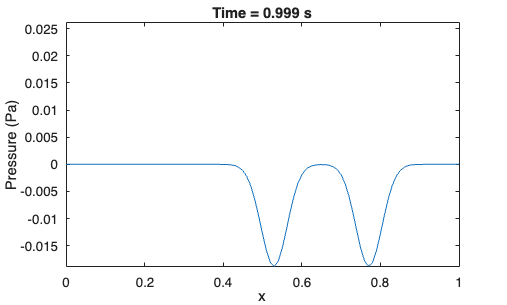

% Running solver
[P,V] = solver.solve(p0,v0,Source=source);

%%
% P and V are both stored on outputGrid at outputTimes. The internal
% pressure and velocity states remain on staggered computational grids.
P.animate;

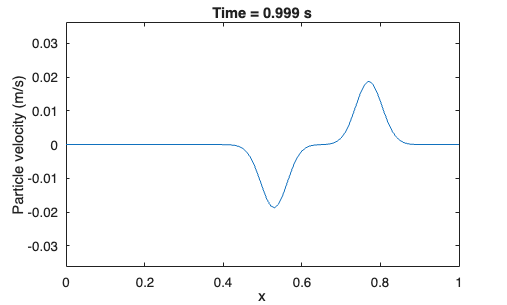

V.animate;